# Fourier Series

**Learning Goals**

- Visualize Fourier series modes.

- Compute the Fourier series of a periodic function.

- Estimate Fourier coefficients numerically.

## *[Some opening motivation here]*

*Could be an application.*

*Could relate to previous material (taylor series).*

*Could talk about defining a signal in terms of "fundamental components": what are the fundamental components of a signal? Are they points? Another basis? For some signals, they are oscillations. For such signals, sines and cosines are excellent descriptors.*

## Fourier Sine and Cosine Series

The Fourier series is most commonly defined as a sum of sines and cosines. Before looking at the full Fourier series, it's helpful to start with a look at cosine and sine series separately. A cosine series is defined as


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right)$$


Similarly, the sine series is


$$f(t) = \sum_{n=1}^\infty b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


$L$ is a parameter the determines the periodicity – in both cases $f$ will have period $2L$. The coefficients $a_n$ and $b_n$ determine how strongly each mode is represented in the overall sum.

*[Need to fill this out. Maybe something from the motivation/description above.]*

    **Activity. ***[Activity 1: simple plot that shows the period (2L) and copies, show the actual expression of a truncated series with less than 5 terms. Mention something about how the cosine series is even and the sine series is odd.] [Alternative: this could simply plot the individual modes.]*

    **Activity. [***Activity 2: Use the app to construct a few pictured or common functions. Might want to make some adjustments to the app to match the text here, like changing to "b_n" and adding "a_0" for the cosine series.]*

[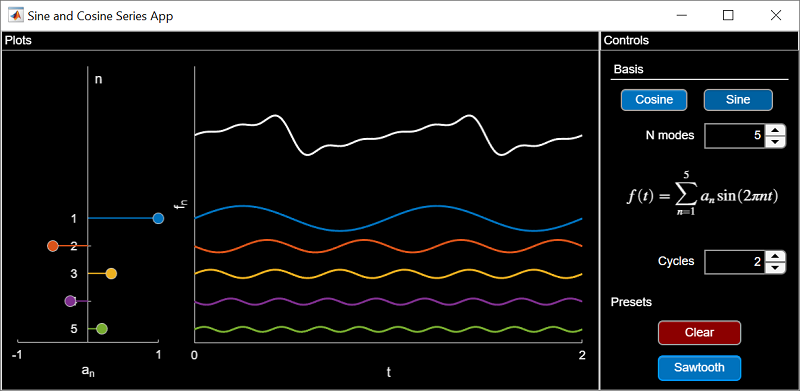](matlab: SinCosSeries)

[SinCosSeries.mlapp](matlab: SinCosSeries)

## Definition

Combine the cosine and sine series together and you have the standard Fourier series.


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right) + b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


    **Activity. **[Activity: build the pictured functions by adjusting the coefficients of the fourier series app.]

[App image]

[InteractiveFourierSeries.mlapp](matlab: InteractiveFourierSeries)

## Solving for Fourier Series Coefficients

[Could put an image here of approximating a function with fourier series]

You can approximate a $2L$ periodic function using Fourier series. As you include more terms in the Fourier series, the approximation will more closely match the original function. The coefficients of the Fourier series that best represent a function can be computed using


$$a_n = \frac{1}{L} \int_{-L}^{L} f(t) \cos \left( \frac{ n \pi }{L} t \right) dt$$



$$b_n = \frac{1}{L} \int_{-L}^{L} f(t) \sin\left( \frac{ n \pi }{L} t \right) dt$$


These integrals calculate the weight of the $n^{th}$ mode required to match the original function. These expressions are independent because the basis functions (the sines and cosines) are orthogonal to each other.

    **Activity. **[Activity: adjust the original function in the app and then note the change to the coefficients.]

[App image]

[InteractiveFourierSeries.mlapp](matlab: InteractiveFourierSeries)

 **Example. **Solve for the Fourier series of the odd square wave with period $2L$ and plot the result.

The odd square wave is pictured below. The coefficient integral is taken on the interval $[-L,L]$.

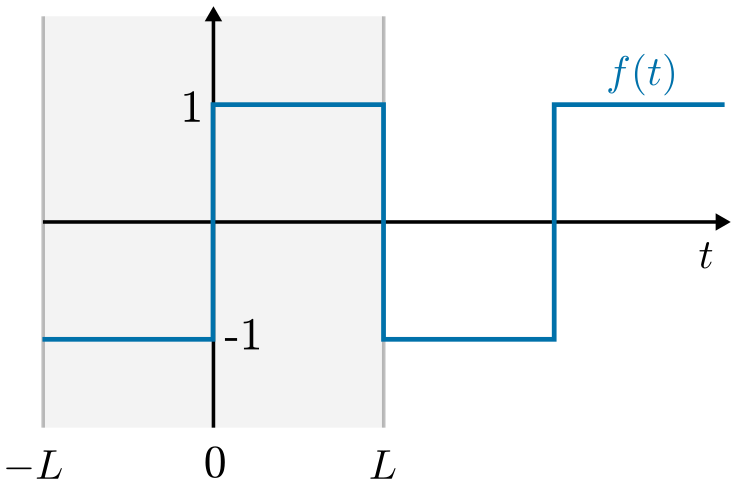

*Odd square wave*

The cosine coefficients $a_n$ are given by


$$a_n = \frac{1}{L} \int_{-L}^{L} f(t) \cos \left( \frac{ n \pi}{L} t \right) dt$$


Because $f(t)$ is odd and the cosine function is even, their product is odd. This implies that the integral is zero, so $a_n = 0$.

To solve for the sine coefficients $b_n$, split the integral on the intervals $[-L,0]$ and $[0,L]$.


$$\begin{array}{rl}
b_n &= \frac{1}{L} \int_{-L}^{L} f(t) \sin \left( \frac{n \pi }{L} t \right) dt 
\\
&=  \frac{1}{L} \left[ - \int_{-L}^{0}  \sin \left( \frac{n \pi}{L} t \right) dt + 
\int_{0}^{L} \sin \left( \frac{ n \pi}{L} t \right) dt  \right]
\end{array}$$


Evaluate the integral to find


$$\begin{array}{rl}
b_n &=  \frac{1}{n \pi} \left[ \left. \cos \left( \frac{n \pi}{L} t \right) \right|_{-L}^0 - 
\left. \cos \left( \frac{n \pi}{L} t \right) \right|_0^L  \right]
\\
&=  \frac{2}{n \pi} \left[ 1 - \cos(n \pi )]
\end{array}$$


Notice that for even $n$, $\cos( n \pi) = 1$, while if $n$ is odd $\cos(n \pi ) = -1$. This implies


$$b_n =
\left\{
\begin{array}{ll} 
0 & n \ \text{ even}
\\
\frac{4}{n \pi} & n \ \text{ odd}
\end{array}
\right.$$


Therefore, the Fourier series approximation is


$$f_s(t) = \sum_{n=1,3,5,\ldots}^\infty \frac{4}{n \pi} \sin \left( \frac{ n \pi } {L}  t \right)$$


Use the slider below to view the partial series plotted alongside the original square wave function.

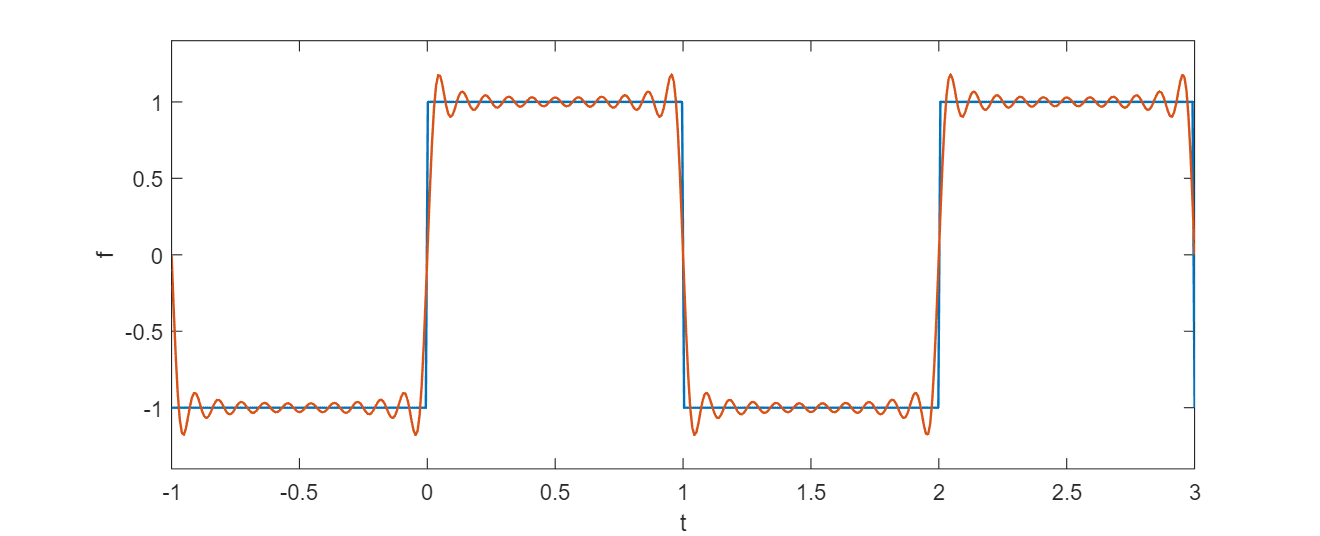

NModes = 11; % How many modes to use
% Compute the coefficients
L = 1;
n = 1:2:(NModes*2);
b = 4./(pi*n);

% Sum the Fourier modes
t = linspace(-L,3*L,500);
fs = zeros(size(t));
for k = 1:numel(n)
    fs = fs + b(k)*sin((n(k)*pi/L).*t);
end
f = square(t*pi/L);

% Plot the result
figure("position",[1,1,800,325])
plot(t,f,t,fs,"linewidth",1.1)
axis([-L,3*L,-1.4,1.4])
xlabel("t")
ylabel("f")

 **Exercise. **Solve for the Fourier series of the odd sawtooth function (pictured below) with period $2L$. Then, follow the instructions to plot the Fourier series.

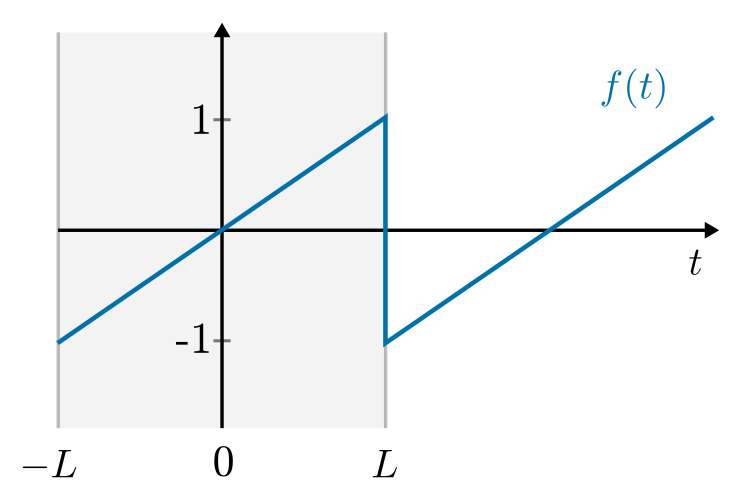

Note that on the interval $[-L,L]$ (where the integral is evaluated), the sawtooth function is simply the linear function:


$$f(t) = \frac{t}{L}$$


**---Solution---**

The function is odd so $a_n = 0$ and


$$\begin{array}{rl}
b_n &= \frac{1}{L} \int_{-L}^{L} \frac{t}{L} \sin \left( \frac{n \pi }{L} t \right) dt 
\\
&=  - \frac{2}{\pi^2 n^2} (\pi n \cos(\pi n) - \sin(\pi n))
\\
&=  - \frac{2 (-1)^n}{\pi n} 
\end{array}$$


So the Fourier series is


$$f_s(t) = \sum_{n=1,3,5,\ldots}^\infty -\frac{2(-1)^n}{n \pi} \sin \left( \frac{ n \pi } {L}  t \right)$$


**---End Solution---**

To plot the result, complete the code below by writing the expression for the Fourier series coefficients and the Fourier series terms. If your solution and code is correct, your Fourier series should approach the sawtooth function.

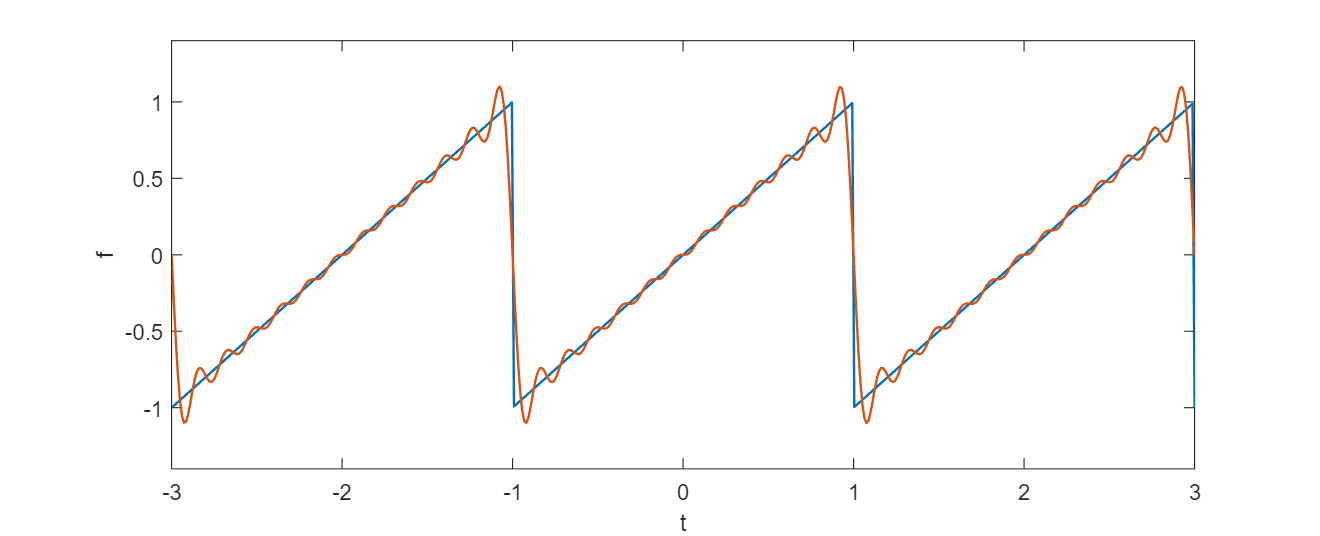

NModes = 12; % How many modes to use
% Compute the coefficients
L = 1;
n = 1:NModes;
% Replace the "NaN" with your expression for the coefficients
b = -2*(-1).^n./(n*pi); %NaN;

% Sum the Fourier modes
t = linspace(-3*L,3*L,500);
fs = zeros(size(t));
for k = 1:numel(n)
    % This loop sums over the Fourier series
    % Replace "NaN" with your expression for the Fourier series
    fs = fs + b(k)*sin(n(k)*pi/L*t);
end
f = sawtooth((t-1)*pi/L);

% Plot the result
figure("position",[1,1,800,325])
plot(t,f,t,fs,"linewidth",1.1)
axis([-3*L,3*L,-1.4,1.4])
xlabel("t")
ylabel("f")

## Numerical Estimation of Fourier Coefficients

In some cases, the Fourier coefficient integrals may be difficult (or impossible) to evaluate analytically. In this situation, you can estimate the Fourier series coefficients numerically. For example, you can estimate $a_n$ numerically using the trapezoid rule as


$$a_n \approx \frac{\Delta t}{2L} \sum_{k=1}^N f(t_{k-1}) \cos \left( \frac{ n \pi }{L} t_{k-1} \right)  + f(t_k) \cos \left( \frac{ n \pi }{L} t_k \right) $$


In this formula, the integral has been discretized into evenly spaced points using $t_k = -L + k \Delta t$ where $\Delta t = 2L/N$. In the formula for $b_n$, the cosines are replaced by sines.

  This method for estimating coefficients is inefficient. Fourier modes can be computed more quickly using the fast fourier transform (FFT). The FFT and its relationship to Fourier series will be discussed in a later module. 

 **Example. **Estimate the Fourier coefficients of the periodic extension of the interpolated function defined below.

Run this section to show the periodic function, $f(t)$. $f$ has a period of 2 (so $L = 1$) and is defined at the end of this script as `ffunc`.

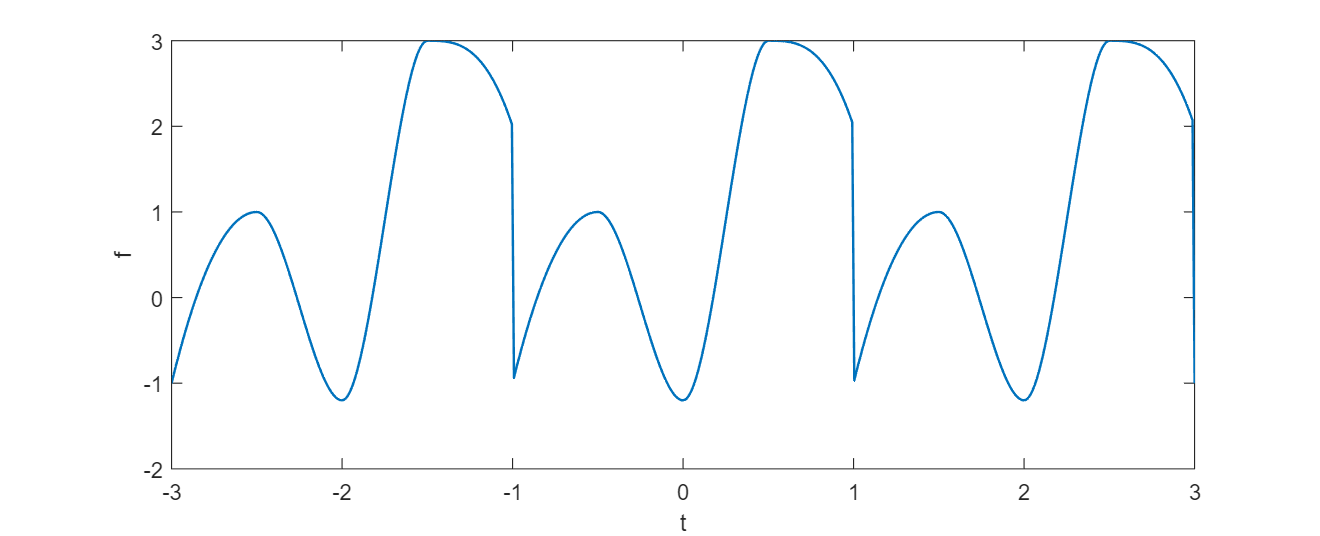

L = 1;
t = linspace(-3*L,3*L,500);
plot(t,ffunc(t),"linewidth",1.1)
xlabel("t")
ylabel("f")

To evaluate the Fourier coefficients, define the number of modes and the integral discretization.

Nmodes = 5; % Number of Fourier modes used in the estimation
N = 100;
deltat = 2*L/N;
% Grid discretization
k = 1:N; 
tk = -L+k*deltat;
tkm1 = -L+(k-1)*deltat;

Then, evaluate the sums to determine the coefficients. Note that $a_0$ is computed outside the loop.

a = zeros(1,Nmodes);
b = zeros(1,Nmodes);
a0 = deltat/(2*L)*sum( ffunc(tkm1) + ffunc(tk));
for n = 1:Nmodes
    a(n) = deltat/(2*L)*sum( ffunc(tkm1).*cos(n*pi/L*tkm1) + ffunc(tk).*cos(n*pi/L*tk));
    b(n) = deltat/(2*L)*sum( ffunc(tkm1).*sin(n*pi/L*tkm1) + ffunc(tk).*sin(n*pi/L*tk));
end
a0

a0 = 1.9154

a

a =    -0.9166   -1.1108   -0.0595   -0.1204    0.1128


b

b =     1.1405   -0.4414    0.2488   -0.2967    0.1811


You can review the Fourier series coefficients by plotting them against $n$.

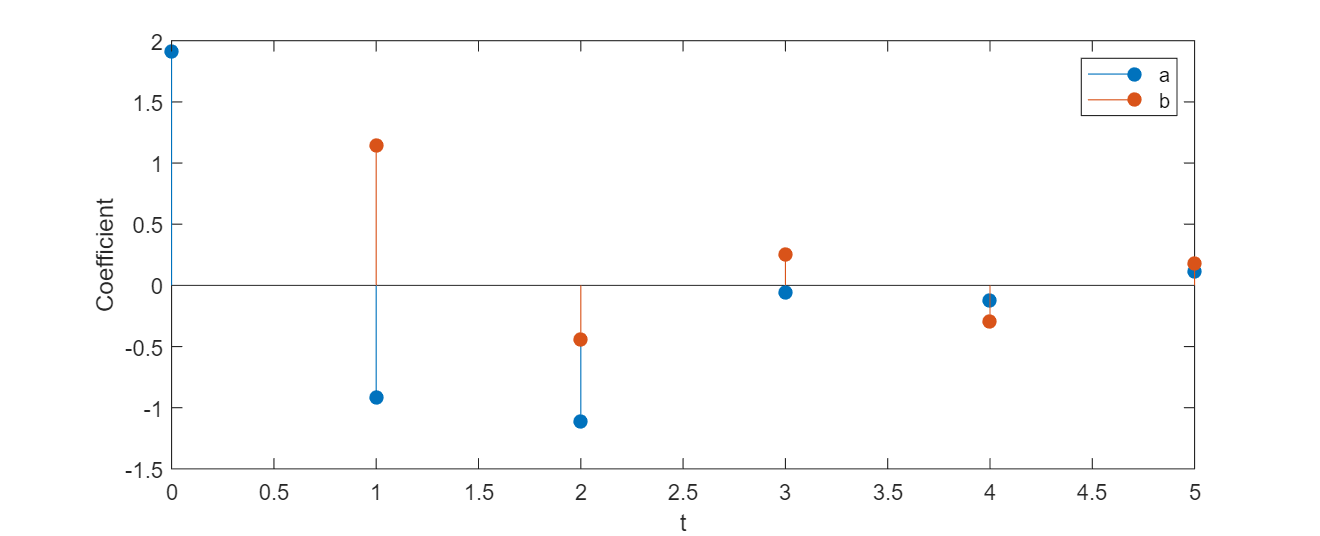

stem(0:Nmodes,[a0,a],"filled")
hold on
stem(1:Nmodes,b,"filled")
hold off
xlabel("t")
ylabel("Coefficient")
legend("a","b")

To review how well the Fourier series approximates the original function, compute the series sum.

% Sum the Fourier modes
t = linspace(-3*L,3*L,500);
fs = a0/2;
for n = 1:Nmodes
    fs = fs + a(n)*cos(n*pi/L*t) + b(n)*sin(n*pi/L*t);
end

Now plot it alongside the original function.

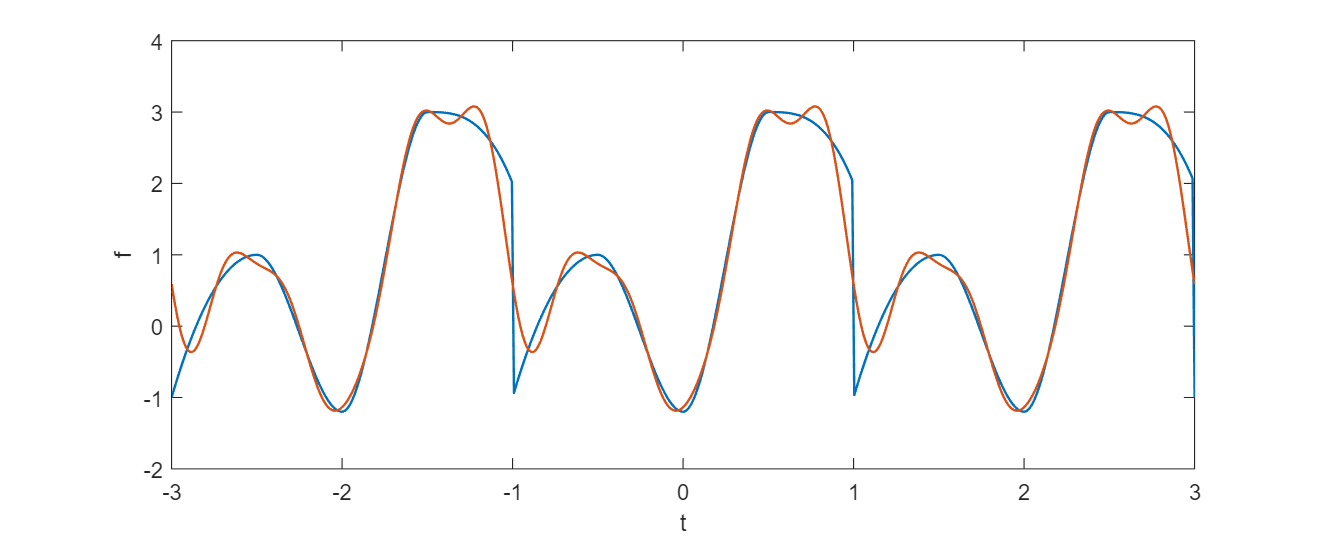

% Plot the result
figure("position",[1,1,800,325])
plot(t,ffunc(t),t,fs,"linewidth",1.1)
xlabel("t")
ylabel("f")

**  Reflect.** 

- Based on the plot of the original function, do you expect more high or low frequency modes to be present?

- Review the plot of the Fourier coefficients. Does the function contain more high or low frequency content?

- Try increasing the number of modes. Does the Fourier series converge? Do you notice any convergence issues?

- If the original function is discontinuous at the boundary, the convergence of the Fourier series is (relatively) poor. A continuous function will have better convergence. 

- Adjust the `ynodes` variable in `ffunc` below so that it has values `[-1,1,-1.2,3,-1]`. This will make the function periodic. Then, rerun the script. Does the convergence of the Fourier series improve?

Helper functions

function f = ffunc(t)
    t = mod(t+1,2)-1;
    xNodes = [-1,-0.5,0,0.5,1]; % Interpolant knot locations
    yNodes = [-1,1,-1.2,3,2];   % Knot values
    f = pchip(xNodes,yNodes,t);
end